### Examples

Example 1

Solve for:

- Estimate x = [ 3, 3 ] with the given data:

% Arranging data
x_data = [1 1; 2 1; 1 2; 2 2];
y_data = [2; 1; 1; 3];
X_to_predict = [1 3 3];

% Performing Linear Regression as a function
[beta, X] = Linear_regression(x_data, y_data);
beta

beta =     0.2500
    0.5000
    0.5000


% Estimating y when x = [3, 3]
y_estimated = X_to_predict * beta

y_estimated = 3.2500

Example 2

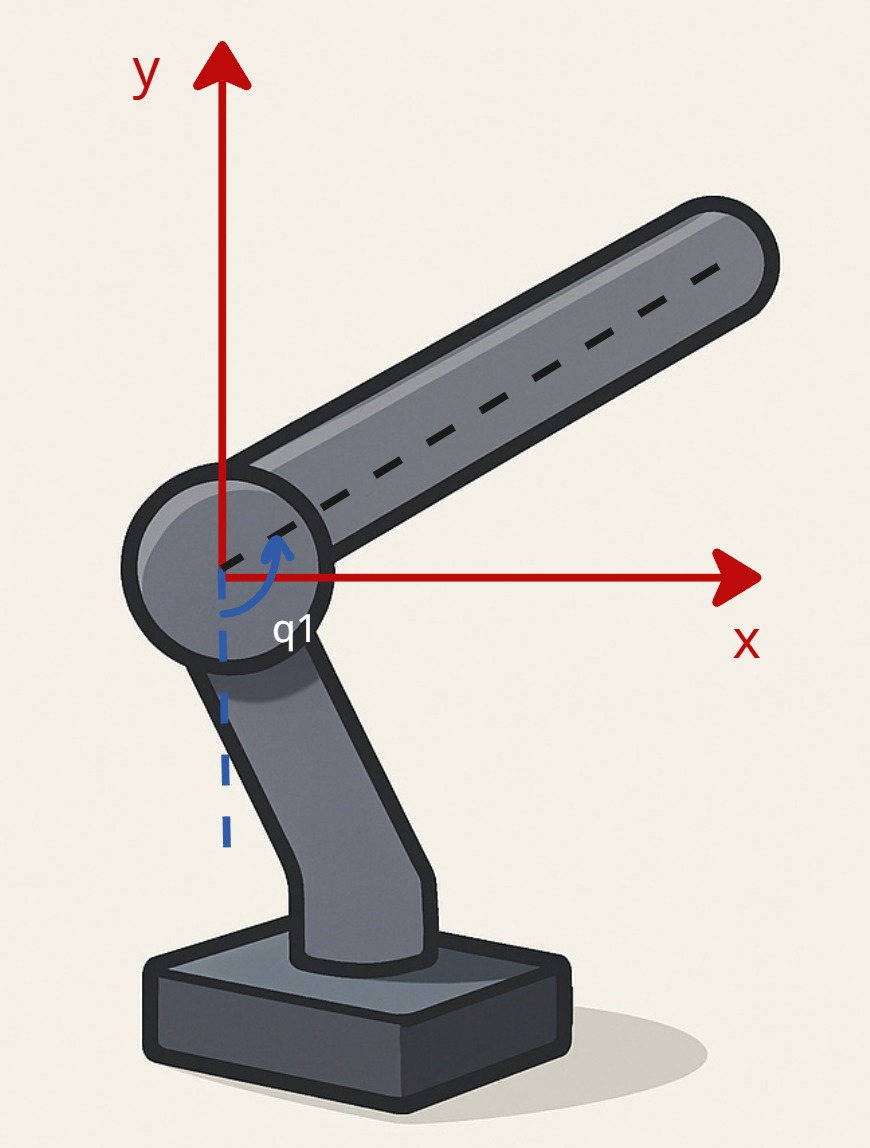

Cinematic model: [ x, y ]^T = [ lp * sin (q1), lp * cos(q1) ]^T

where:

- x and y are cartesian coodinates.

- lp is the limb's length.

- q1 is servomotor's articular coordinate.

Solve for:

- Linear regression model

- Estimate the limb's length (considering a theoric length of lp = 0.45 and random of random data q1)

% Arranging data
lp = 0.45;
q1_data = rand;

coords_data = [sin(q1_data); -cos(q1_data)];

x = lp * sin(q1_data);
y = lp * -cos(q1_data);
coords_real_data = [x; y];

% Performing Linear Regression as a function
[beta, X] = Linear_regression(coords_data, coords_real_data);

% Observation: beta1 = lp
beta

beta =          0
    0.4500


% Comprobation: Turning q1 90 degrees (pi/2 rads) to prove that [x, y]^T = [lp, 0]^T
X_to_predict = [1 sin(pi/2); 1 -cos(pi/2)];

y_estimated = X_to_predict * beta

y_estimated =     0.4500
   -0.0000


Example 3

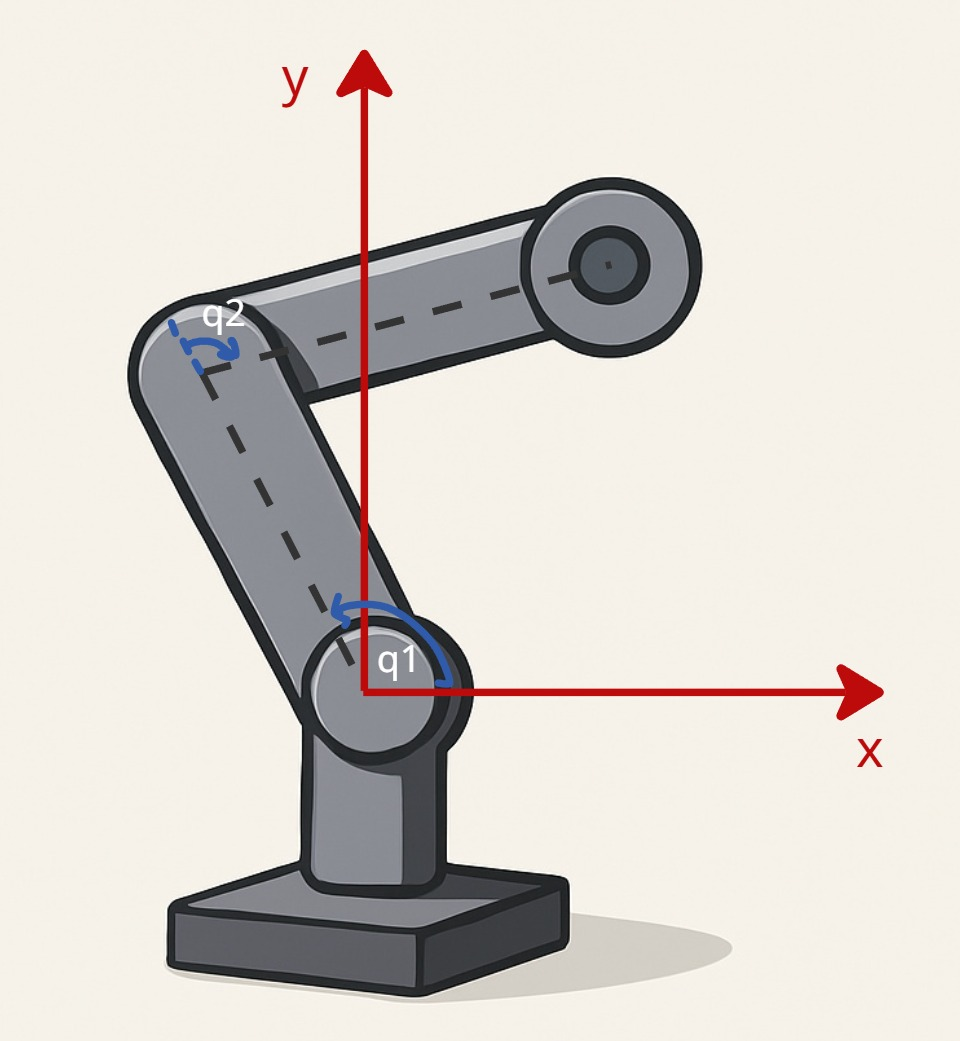

Cinematic model: [ xr, yr ]^T = [ L1 * cos(q1) + L2 * cos(q1 + q2), L1 * sin(q1) + L2 * sin(q1 + q2) ]^T

where:

- xr and yr are cartesian coodinates.

- L1 and L2 are the limb's length (limb 1 and limb 2 respectively).

- q1 and q2 are servomotor's articular coordinates.

Solve for:

- Linear regression model

- Estimate the limb's length (L1 and L2), given: q1 = [ 0, 0.1, 0.2, 0.6, 0.8, 0.7, 0.6, 0.8, 0.78, 0.12 ] rads and q2: [ 0.1, 0.2, 0.3, 0.7, 0.9, 0.8, 0.7, 0.9, 0.68, 0.25 ] rads

% Arranging data
q1_data = [0, 0.1, 0.2, 0.6, 0.8, 0.7, 0.6, 0.8, 0.78, 0.12];
q2_data = [0.1, 0.2, 0.3, 0.7, 0.9, 0.8, 0.7, 0.9, 0.68, 0.25];

L1 = rand

L1 = 0.2435

L2 = rand

L2 = 0.9293

coords_real_data = []; coords_data = [];
for i = 1:length(q1_data)
    q1 = q1_data(i);
    q2 = q2_data(i);
    
    xr = L1 * cos(q1) + L2 * cos(q1 + q2);
    yr = L1 * sin(q1) + L2 * sin(q1 + q2);
    
    coords_data = [coords_data; [cos(q1), cos(q1 + q2); sin(q1), sin(q1 + q2)]];
    coords_real_data = [coords_real_data; [xr; yr]];
end

% Performing Linear Regression as a function
[beta, X] = Linear_regression(coords_data, coords_real_data);

% Observation: beta1 = L1 and beta2 = L2
beta

beta =     0.0000
    0.2435
    0.9293


% Comprobation: Turning q1 and q2 0 and 90 degrees, respectively, to prove that [x, y]^T = [L1, L2]^T
q1 = 0;
q2 = pi/2;

X_to_predict = [1 cos(q1) cos(q1 + q2); 1 sin(q1) sin(q1 + q2)];

y_estimated = X_to_predict * beta

y_estimated =     0.2435
    0.9293
